clc; clear; close all;
% Import functions path
addpath(genpath(strcat(pwd, '\Functions')))
addpath(genpath(strcat(pwd, '\Functions\Globals')))

setTransform("FFT");
setPreamble("Default");

% Parameters
filename='Test/test_file.txt';
fileID = fopen(filename,'r');
data = fread(fileID, '*ubit1', 'ieee-le');
L = 1000;
R = 6;
codeRate = 1/2;
modulation_type = 'BPSK';
rep_type = 'Float';

% Transmitter
setPreamble("double");
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
equalization_method = 'Weiner';
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
output_fileID = fopen('Output/output_test1_BPSK_6_3.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

## Investigating the effect of Preamble Length

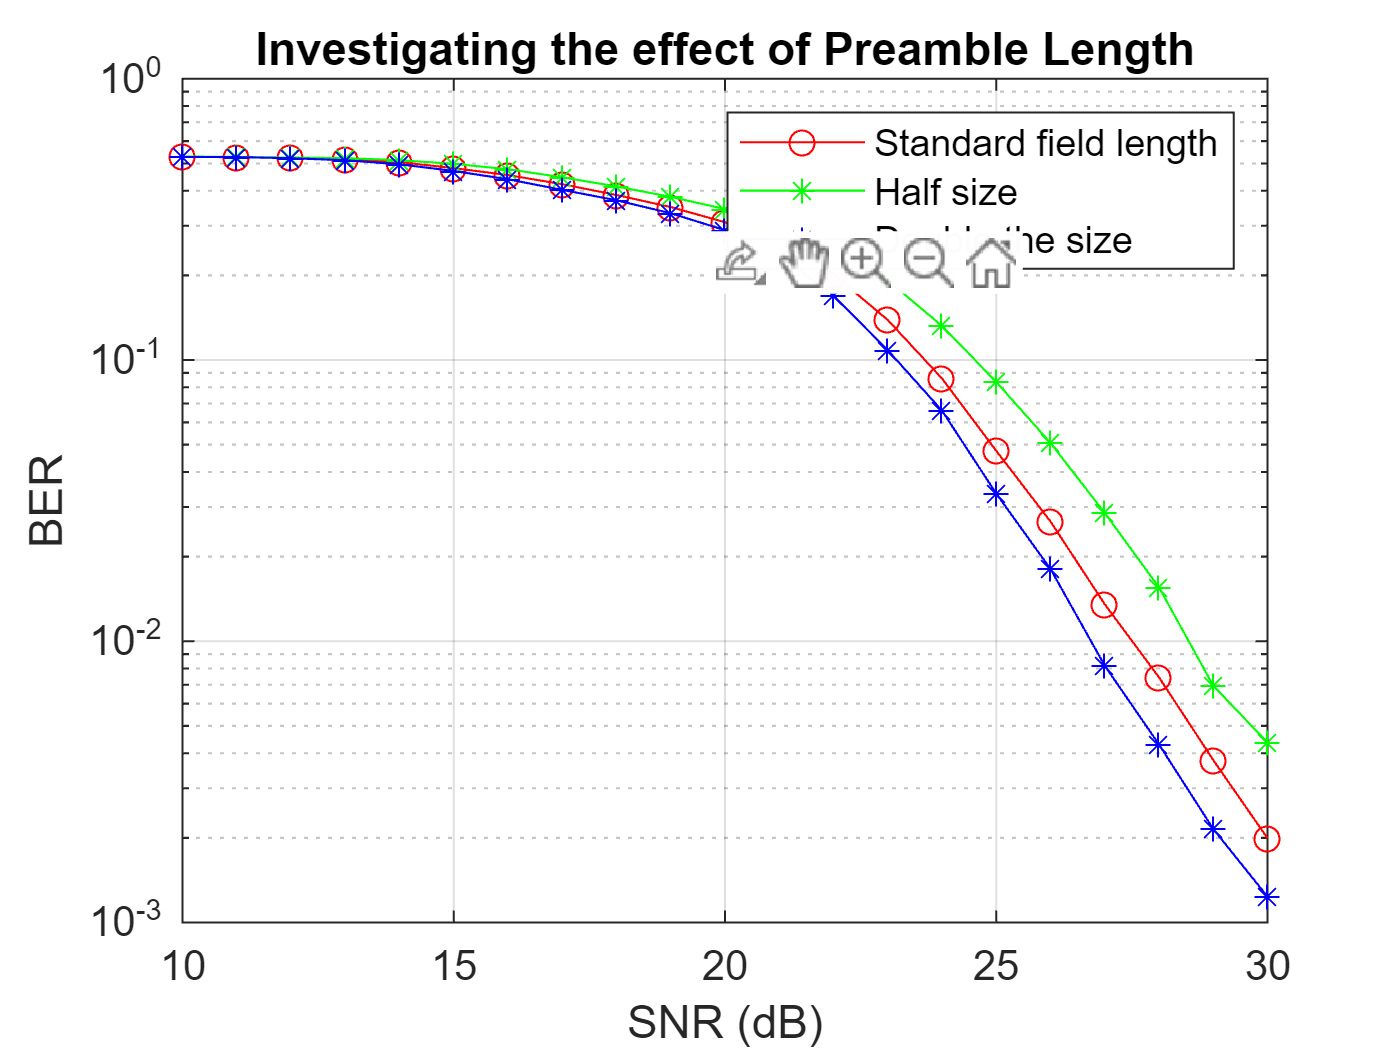

SNR_DB_Arr = 10:30;
L = 1000;
R = 54;
codeRate = 3/4;
modulation_type = '64QAM';
rep_type = 'Float';
equalization_method = 'Weiner';

setPreamble("");
BER_Vals_default_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_default_preamble = [BER_Vals_default_preamble ratio];
end
setPreamble("half");
BER_Vals_half_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_half_preamble = [BER_Vals_half_preamble ratio];
end
setPreamble("double");
BER_Vals_double_preamble = [];
for snr = SNR_DB_Arr
    % Transmitter
    transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
    % Channel
    rxed_frames = apply_channel(transmitted_frames, snr);
    % Receiver
    equalization_method = 'Weiner';
    [decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, snr);
    [BER, ratio] = biterr(decoded_data',data);
    BER_Vals_double_preamble = [BER_Vals_double_preamble ratio];
end
figure();
semilogy(SNR_DB_Arr, BER_Vals_default_preamble,'r-o', ...
    SNR_DB_Arr, BER_Vals_half_preamble,'g-*', ...
    SNR_DB_Arr, BER_Vals_double_preamble, 'b-*');
title('Investigating the effect of Preamble Length');
xlabel('SNR (dB)'); ylabel('BER');
grid on;
legend('Standard field length', 'Half size', 'Double the size');

## Investigating the effect of the transform techniques

L = 1000;R = 54;codeRate = 3/4;modulation_type = '64QAM';rep_type = 'Float';equalization_method = 'Weiner';
setPreamble("Default");
setTransform("FFT");
% ====== FFT ========
disp("For FFT:-")

For FFT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 2.009171 seconds.


output_fileID = fopen('Output/test2_fft.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');

% ====== DCT ========
setTransform("DCT");
disp("For DCT:-")

For DCT:-


tic
% Transmitter
transmitted_frames = Wifi_Transmitter(data, L, R, codeRate, modulation_type, rep_type);
% Channel
rxed_frames = apply_channel(transmitted_frames, 30);
% Receiver
[decoded_data, ~, ~] = Wifi_Receiver(rxed_frames, equalization_method, rep_type, 0);
toc

Elapsed time is 4.814966 seconds.


output_fileID = fopen('Output/test2_dct.txt','w');
y = fwrite(output_fileID, decoded_data,'*ubit1', 'ieee-le');